# Exercise 1

## Defining a Simple Potential Function

### About This Exercise

You previously encountered the concept of the Sense-Act loop, and over the past few courses we have focused on the sensing part. In this and the remaining courses, we will return to the act part of the loop, where will create control inputs that reach the goal while avoiding obstacles. This is otherwise known as motion planning. There are numerous methods for solving the motion planning problem that were introduced in the videos, and this course focuses on building continuous potential functions that will define the control input for any pose of the robot.

Imagine yourself on a snowy landscape of rolling hills with a saucer sled. One you get on, your path down the hill will largely be determined by gravity and the shape of the terrain. Now imagine you have the power to shape the terrain to your liking, so that the place you want to end up is at the bottom of the valley and places you want to avoid are made into impossibly steep slopes. By altering the terrain, you are in effect controlling where your sled will go through gravity. We can similarly control the robot velocities by defining a potential function, where the controls are dependent on that function such that the robot moves towards its goal avoiding obstacles, just like the sled. The control velocities are defined by the negative gradient of that function, which means it always points towards the steepest downward direction, and the steeper it is, the faster the robot will go. 

In this exercise, you will start with some simple potential function, without any obstacles, that are shaped like bowls, where there is a global minimum at the goal and the function gets higher the further you move away from the goal. Remember, however, that it is not the height of the function that determines the control, but the magnitude of the gradient.

**By the end of this exercise, you'll be able to: **

- **Drive a holonomic robot towards a goal using potential functions.**

**Defining Simple Potential Functions**

First we need to write functions that will calculate the potential and gradients at input points for a given goal point and gain factor C. In the video, we introduced two possible ways to define the potential function, using a linear or a quadratic equation and each method has its own pros and cons. 

[► Write the linear potential function](matlab:open('./linearPotential.mlx'))

[► Write the quadratic potential function](matlab:open('./quadraticPotential.mlx'))

Once you have finished both the linearand quadratic potential functions, this section will visualize the linear (left) and quadratic (right) potential function and gradient. Adjust the goal position and the gain factor C.How does do the two potential functions differ? How does C affect the shape of the function?

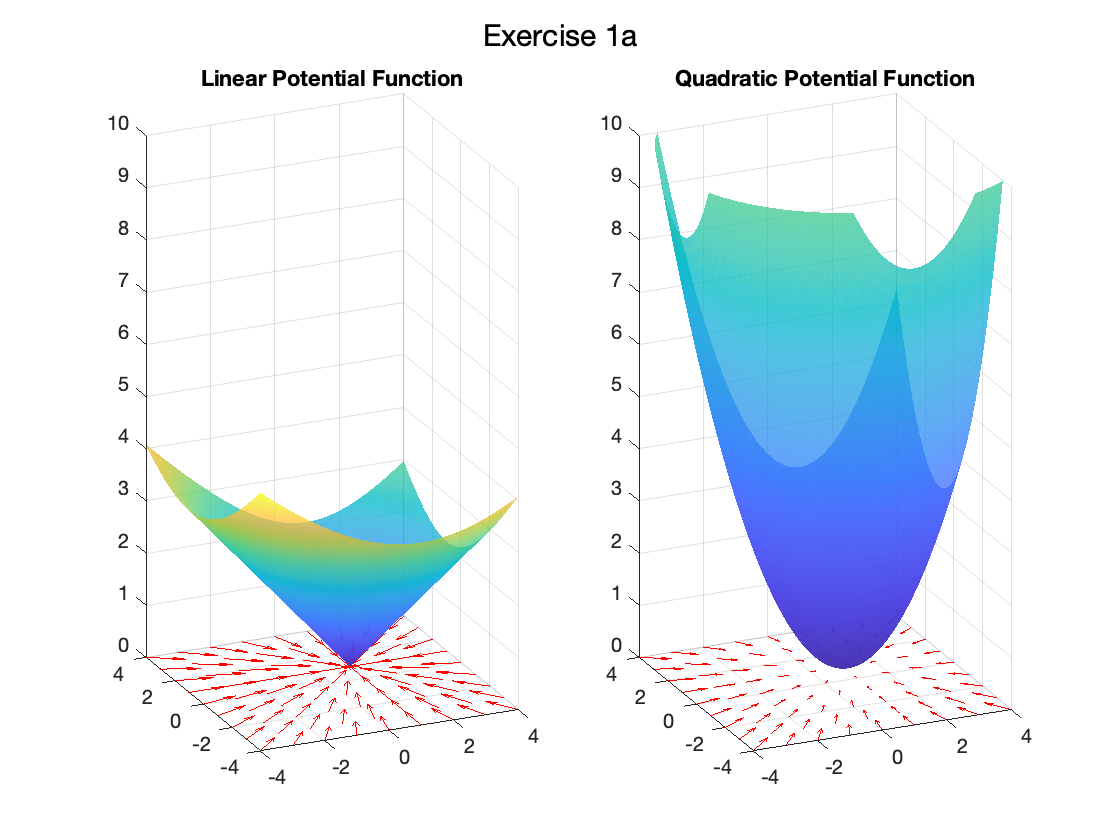


goal_x =1; %Change Value here [-4,4]
goal_y = 1; %Change Value here [-4,4]
C  = 0.7; %Change Value here [0,1]

dx = 0.1;
x = -4:dx:4;
y = x;
[X,Y] = meshgrid(x,y);
[Ugrid, dUdx, dUdy] = linearPotential(X,Y,[goal_x,goal_y],C);
[Ugrid2,dUdx2,dUdy2] = quadraticPotential(X,Y,[goal_x,goal_y],C);
plot_title = "Exercise 1a"; 
[indx, indy] = plotPotentials(dUdx, dUdy, X, Y, Ugrid,Ugrid2, dUdx2, dUdy2, plot_title);

### Using the Potential Function for Robot Control

Remember that we are using the gradient of the potential function to actually control the robot. For the case of the holonomic robot, the control is $u = [V_x, V_y] = -\nabla U$, which you have already implemented in the potential functions. We can visualize the gradient and therefore the control at a given point using a vector field in 2D. The robot will drive in the direction of the vector at a speed equal to the magnitude of the vector. In this section, the vectors are unscaled, so they show the true velocity that will be used as the control of the robot.

In both potential functions, all vectors should point directly towards the goal. What is different is the magnitude of the vectors. Use the following code to animate the control of a holonomic robot for the two potential functions side-by-side. Run the entire script (instead of the individual section) and change the values for the start position, goal, and C. 

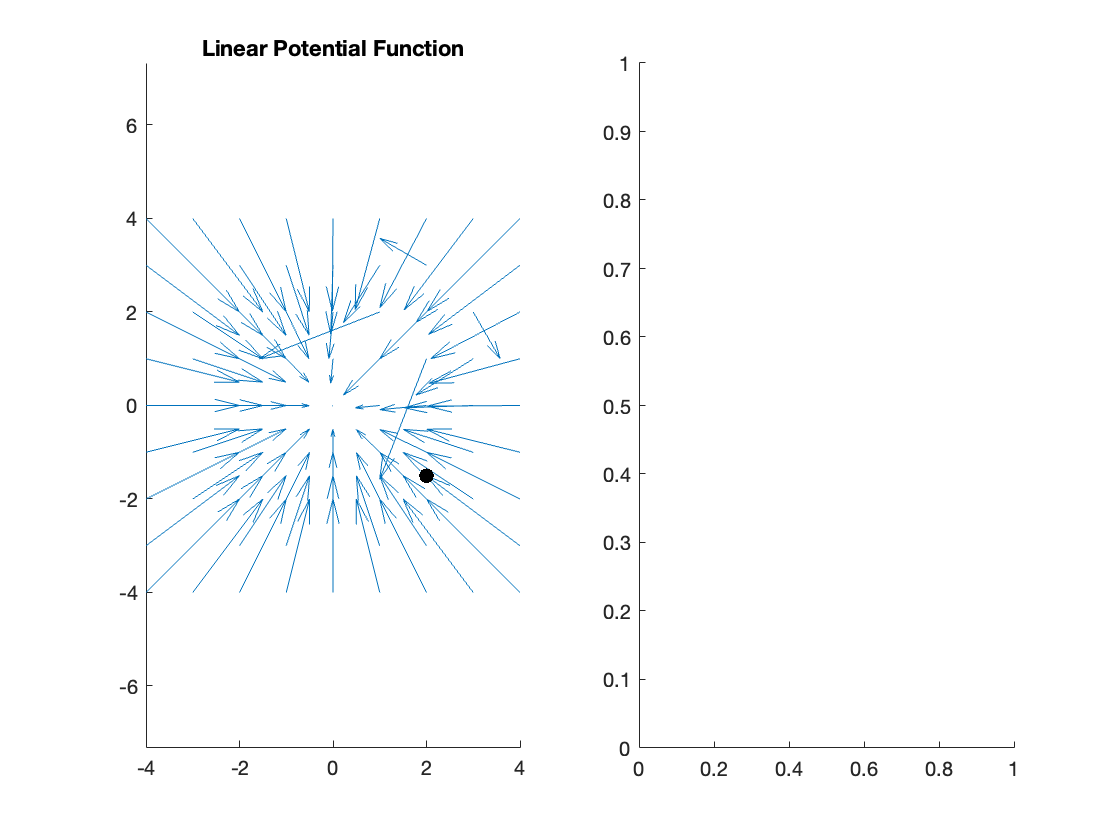

start_x = 2; %Change Value here [-4,4]
start_y =-1.5; %Change Value here [-4,4]

plot_title = "Exercise 1b";  
animate_robot(X, indx, indy, Y, dUdx, dUdy, start_x, start_y, dUdx2, dUdy2, goal_x, goal_y, C, plot_title);

How does the magnitude of the control change as you get closer to the goal for the two functions? What are the advantages and disadvantages to each function? In the videos, we mention that you might want to combine the two functions together, using the linear one further away and the quadratic as the robot gets closer. You have actually already implemented this exact control scheme before in the first course by scaling the control based off of the difference between the pose and the goal coordinates and limiting the commands to be below a certain value. What then is the use of introducing the added complexity of a potential function? 

**Finished!**

You have successfully deifined a potential function to control a robot. In the next exercise, you will further shape these functions to include obstacles, and find that they are a useful generalized tool for motion planning.